images = imageDatastore("data\", "IncludeSubfolders", true, "LabelSource", "foldernames");
countEachLabel(images)
img_classes = {'pos', 'neg_64'};

train_count = 2300;
test_count = 100;

[images_train, images_test] = splitEachLabel(images, train_count, test_count, 'Include', img_classes);



% Przygotowanie danych treningowych
X_train = zeros(length(images_train.Files), 3780);
Y_train = images_train.Labels;

for i=1:length(images_train.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_train.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_train(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_train.Files{i});
        fprintf("Error: %s", ME);
    end
end



% Przygotowanie danych testowych
X_test = zeros(length(images_test.Files), 3780);
Y_test = images_test.Labels;

for i=1:length(images_test.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_test.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        % imshow(I, 'InitialMagnification', 500);
        % hold on;
        % plot(vis);
        X_test(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_test.Files{i});
        fprintf("Error: %s", ME);
    end
end


model = fitcknn(X_train,Y_train,'NumNeighbors',50,'Standardize',1);


clear loss;
loss_s = loss(model, X_test, Y_test, 'Lossfun', 'classiferror');
fprintf("loss=%f\n", loss_s);
preds = model.predict(X_test);

C = confusionmat(Y_test, preds);

TP = diag(C);         % True positives for each class
FN = sum(C, 2) - TP;  % False negatives for each class

recall = TP ./ (TP + FN)
averageRecall = mean(recall)

figure;
It = imread("people_1.jpg");
imshow(It);
hold on
[hogt,vist] = extractHOGFeatures(It);
plot(vist)

scale = 1

count_x = 77

count_y = 34

level=1 count_x=77 count_y=34

level=1 0/2618 (j=0, i=0)... 
level=1 1/2618 (j=0, i=1)... 
level=1 2/2618 (j=0, i=2)... 
level=1 3/2618 (j=0, i=3)... 
level=1 4/2618 (j=0, i=4)... 
level=1 5/2618 (j=0, i=5)... 
level=1 6/2618 (j=0, i=6)... 
level=1 7/2618 (j=0, i=7)... 
level=1 8/2618 (j=0, i=8)... 
level=1 9/2618 (j=0, i=9)... 
level=1 10/2618 (j=0, i=10)... 
level=1 11/2618 (j=0, i=11)... 
level=1 12/2618 (j=0, i=12)... 
level=1 13/2618 (j=0, i=13)... 
level=1 14/2618 (j=0, i=14)... 
level=1 15/2618 (j=0, i=15)... 
level=1 16/2618 (j=0, i=16)... 
level=1 17/2618 (j=0, i=17)... 
level=1 18/2618 (j=0, i=18)... 
level=1 19/2618 (j=0, i=19)... 
level=1 20/2618 (j=0, i=20)... 
level=1 21/2618 (j=0, i=21)... 
level=1 22/2618 (j=0, i=22)... 
level=1 23/2618 (j=0, i=23)... 
level=1 24/2618 (j=0, i=24)... 
level=1 25/2618 (j=0, i=25)... 
level=1 26/2618 (j=0, i=26)... 
level=1 27/2618 (j=0, i=27)... 
level=1 28/2618 (j=0, i=28)... 
level=1 29/2618 (j=0, i=29)... 
level=1 30/2618 (j=0, i=30)... 
level=1 31/2618 (j=0, i=31).

best_score = 0

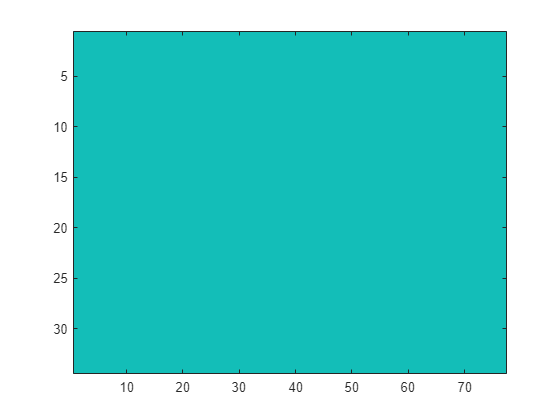

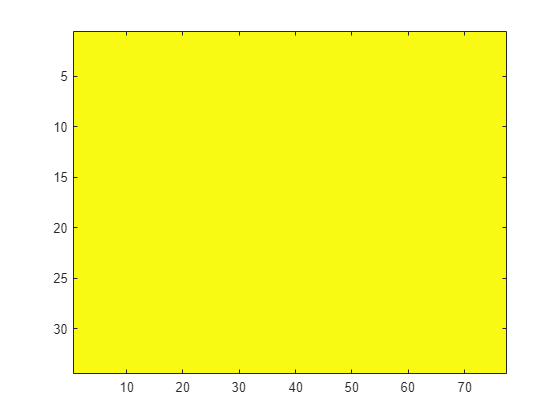

scale = 0.8000

count_x = 60

count_y = 24

level=2 count_x=60 count_y=24

level=2 0/1440 (j=0, i=0)... 
level=2 1/1440 (j=0, i=1)... 
level=2 2/1440 (j=0, i=2)... 
level=2 3/1440 (j=0, i=3)... 
level=2 4/1440 (j=0, i=4)... 
level=2 5/1440 (j=0, i=5)... 
level=2 6/1440 (j=0, i=6)... 
level=2 7/1440 (j=0, i=7)... 
level=2 8/1440 (j=0, i=8)... 
level=2 9/1440 (j=0, i=9)... 
level=2 10/1440 (j=0, i=10)... 
level=2 11/1440 (j=0, i=11)... 
level=2 12/1440 (j=0, i=12)... 
level=2 13/1440 (j=0, i=13)... 
level=2 14/1440 (j=0, i=14)... 
level=2 15/1440 (j=0, i=15)... 
level=2 16/1440 (j=0, i=16)... 
level=2 17/1440 (j=0, i=17)... 
level=2 18/1440 (j=0, i=18)... 
level=2 19/1440 (j=0, i=19)... 
level=2 20/1440 (j=0, i=20)... 
level=2 21/1440 (j=0, i=21)... 
level=2 22/1440 (j=0, i=22)... 
level=2 23/1440 (j=0, i=23)... 
level=2 24/1440 (j=0, i=24)... 
level=2 25/1440 (j=0, i=25)... 
level=2 26/1440 (j=0, i=26)... 
level=2 27/1440 (j=0, i=27)... 
level=2 28/1440 (j=0, i=28)... 
level=2 29/1440 (j=0, i=29)... 
level=2 30/1440 (j=0, i=30)... 
level=2 31/1440 (j=0, i=31).

best_score = 0

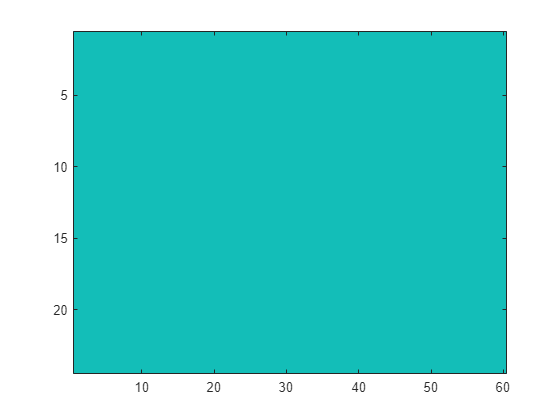

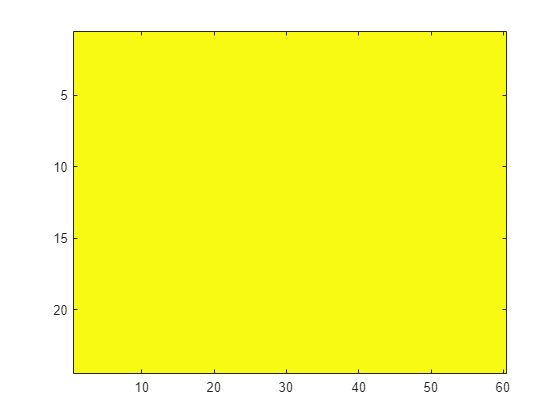

scale = 0.6400

count_x = 46

count_y = 16

level=3 count_x=46 count_y=16

level=3 0/736 (j=0, i=0)... 
level=3 1/736 (j=0, i=1)... 
level=3 2/736 (j=0, i=2)... 
level=3 3/736 (j=0, i=3)... 
level=3 4/736 (j=0, i=4)... 
level=3 5/736 (j=0, i=5)... 
level=3 6/736 (j=0, i=6)... 
level=3 7/736 (j=0, i=7)... 
level=3 8/736 (j=0, i=8)... 
level=3 9/736 (j=0, i=9)... 
level=3 10/736 (j=0, i=10)... 
level=3 11/736 (j=0, i=11)... 
level=3 12/736 (j=0, i=12)... 
level=3 13/736 (j=0, i=13)... 
level=3 14/736 (j=0, i=14)... 
level=3 15/736 (j=0, i=15)... 
level=3 16/736 (j=0, i=16)... 
level=3 17/736 (j=0, i=17)... 
level=3 18/736 (j=0, i=18)... 
level=3 19/736 (j=0, i=19)... 
level=3 20/736 (j=0, i=20)... 
level=3 21/736 (j=0, i=21)... 
level=3 22/736 (j=0, i=22)... 
level=3 23/736 (j=0, i=23)... 
level=3 24/736 (j=0, i=24)... 
level=3 25/736 (j=0, i=25)... 
level=3 26/736 (j=0, i=26)... 
level=3 27/736 (j=0, i=27)... 
level=3 28/736 (j=0, i=28)... 
level=3 29/736 (j=0, i=29)... 
level=3 30/736 (j=0, i=30)... 
level=3 31/736 (j=0, i=31)... 
level=3 32/736 (j=0, i=32)..

best_score = 0

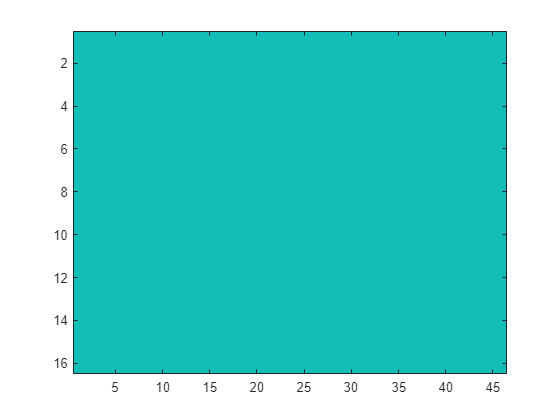

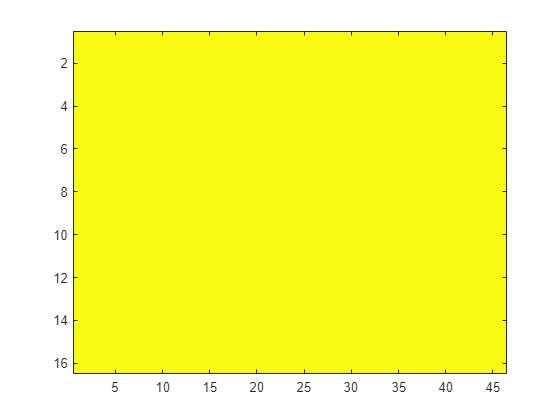

scale = 0.5120

count_x = 35

count_y = 9

level=4 count_x=35 count_y=9

level=4 0/315 (j=0, i=0)... 
level=4 1/315 (j=0, i=1)... 
level=4 2/315 (j=0, i=2)... 
level=4 3/315 (j=0, i=3)... 
level=4 4/315 (j=0, i=4)... 
level=4 5/315 (j=0, i=5)... 
level=4 6/315 (j=0, i=6)... 
level=4 7/315 (j=0, i=7)... 
level=4 8/315 (j=0, i=8)... 
level=4 9/315 (j=0, i=9)... 
level=4 10/315 (j=0, i=10)... 
level=4 11/315 (j=0, i=11)... 
level=4 12/315 (j=0, i=12)... 
level=4 13/315 (j=0, i=13)... 
level=4 14/315 (j=0, i=14)... 
level=4 15/315 (j=0, i=15)... 
level=4 16/315 (j=0, i=16)... 
level=4 17/315 (j=0, i=17)... 
level=4 18/315 (j=0, i=18)... 
level=4 19/315 (j=0, i=19)... 
level=4 20/315 (j=0, i=20)... 
level=4 21/315 (j=0, i=21)... 
level=4 22/315 (j=0, i=22)... 
level=4 23/315 (j=0, i=23)... 
level=4 24/315 (j=0, i=24)... 
level=4 25/315 (j=0, i=25)... 
level=4 26/315 (j=0, i=26)... 
level=4 27/315 (j=0, i=27)... 
level=4 28/315 (j=0, i=28)... 
level=4 29/315 (j=0, i=29)... 
level=4 30/315 (j=0, i=30)... 
level=4 31/315 (j=0, i=31)... 
level=4 32/315 (j=0, i=32)..



% Weryfikacja klasyfikatora
sx = 64;
sy = 128;
step = 8;

scale_step = 0.8;
levels = 5;

scale = 1.0;
thr = 0;

dets = [];
scores = [];
labels = {};


for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step)
count_y = floor((h - sy) / step)

fprintf("level=%d count_x=%d count_y=%d", k, count_x, count_y)

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        fprintf("level=%d %d/%d (j=%d, i=%d)... \n", k, j*count_x+i, count_y*count_x, j, i);
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        [sub_hog, sub_vis] = extractHOGFeatures(sub_img);
        [pred, scores] = model.predict(sub_hog);
        if scores(1) == 1
            scores
        end
        out(j+1, i+1) = strcmp(pred, 'pos');
    end
end

best_score = min(min(out))

figure;
imagesc(out)
figure;
mins = imregionalmin(out);
mins(out > thr) = 0;
imagesc(mins);
[rs, cs] = find(mins);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;

    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = min(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

gt_rect=gTruth.LabelData.person{1,1};
ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);
score_thr = 30;
selected_dets = filtered_dets(filtered_scores < score_thr, :);
ratio = bboxOverlapRatio(gt_rect, selected_dets)
[best_overlaps, good_ids] = max(ratio, [], 2)
iou = 0.4;
best_ids = good_ids(best_overlaps > iou)
pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
imshow(ann2)

[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");
figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");
ap = trapz(R, P)

function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [0, sorted_scores];
    sc = sorted_scores;
    
    all_pos = size(gt_rect, 1);
    
    P(1) = 1;
    R(1) = 0;
    
    for ii=2:cnt
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores <= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end